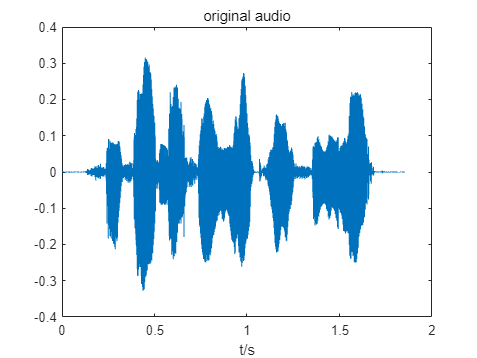

close all; clear; clc;
[y, fs] = audioread('C_01_02.wav');
y=y.';
t = (0:length(y)-1)/fs;
figure;
plot(t, y);title('original audio');xlabel('t/s');

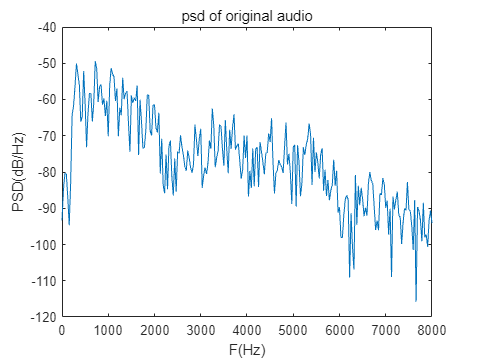


% step 1 psd of origin audio
sig = repmat(y, 1, 10);
[pxx, w] = pwelch(sig, [], [], 512, fs);

figure;
plot(w, 10*log10(pxx));title('psd of original audio'); 
xlabel('F(Hz)'); ylabel('PSD(dB/Hz)');

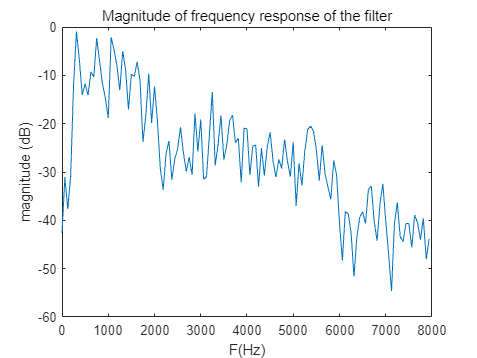


% step 2b generate filter coefficients
b = fir2(3000, w/(fs/2), sqrt(pxx/max(pxx)));
[h, wh] = freqz(b,1,128,fs);
figure;
plot(wh, 20*log10(abs(h)));
title('Magnitude of frequency response of the filter');
xlabel('F(Hz)'); ylabel('magnitude (dB)');

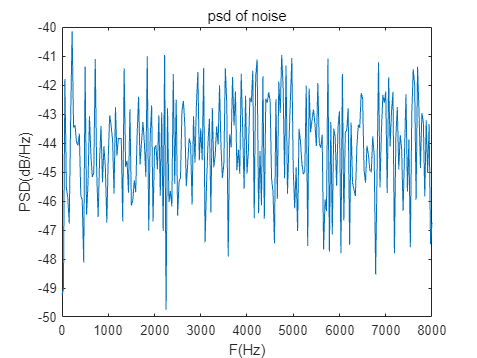


% step 2c1 perform filter for white noise; generate noise
noise = 1 - 2*rand(1, length(y));
[pxxn, wn] = pwelch(noise, [], [], 512, fs);
figure;
plot(wn, 10*log10(pxxn));
title('psd of noise'); 
xlabel('F(Hz)'); ylabel('PSD(dB/Hz)');

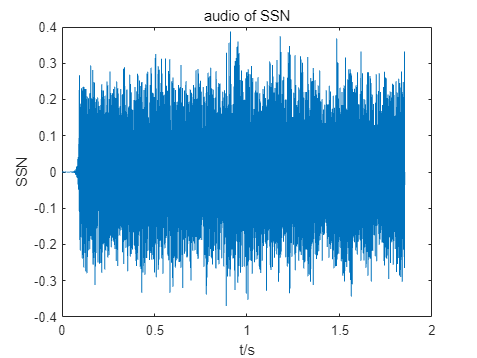

% step 2c2 perform filter for white noise; perfoem filter
SSN = filter(b, 1, noise);
figure;
plot(t,SSN);title('audio of SSN');
xlabel('t/s');ylabel('SSN');

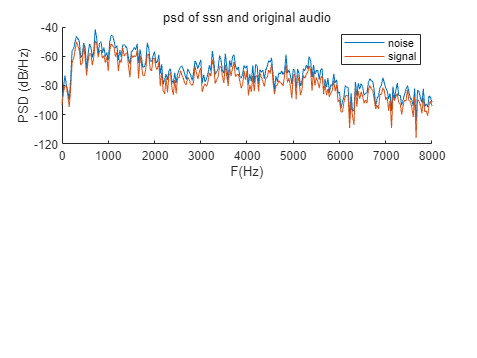

[pxx_ssn, wyn] = pwelch(SSN, [], [], 512, fs);
figure;
subplot(211); hold('on');
plot(wyn, 10*log10(pxx_ssn));
plot(w, 10*log10(pxx));
legend('noise', 'signal');
title('psd of ssn and original audio'); xlabel('F(Hz)'); ylabel('PSD (dB/Hz)');

audiowrite('ssn.wav',SSN,fs);

